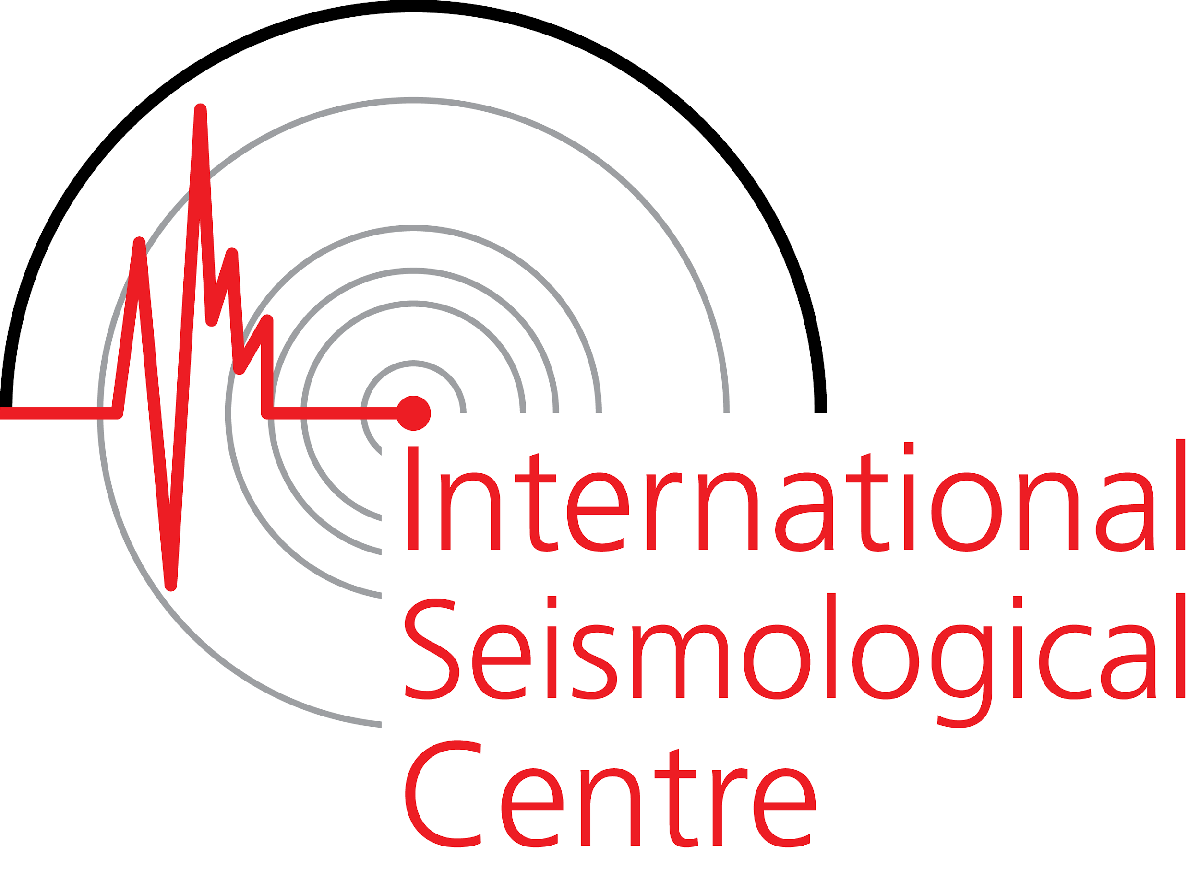

**Search the ISC Bulletin**

Set the **search type** for the bulletin search:

% Set search type
clear all; close all;
setupISCtoolbox; % Adds the paths to Functions etc
search_type = 'P';

if search_type == 'P'
    disp('NOTE: Polygon mode selected');
    disp('If search type selected is POLYGON you must then interactively describe the polygon in the pop up map');
    disp('If you are using this Live Script via MATLAB online, the interactive map will appear inline. For offline');
    disp('versions, the map appears as a pop up.');
end

NOTE: Polygon mode selected


If search type selected is POLYGON you must then interactively describe the polygon in the pop up map


If you are using this Live Script via MATLAB online, the interactive map will appear inline. For offline


versions, the map appears as a pop up.


Set the **start date and time** for the bulletin search:

% Set start year
default_start_year = 2022;
start_year = 1964; start_month  = 1;      start_day = 1;
if eomday(start_year,start_month) < start_day
    start_day = eomday(start_year,start_month);
end
start_hour   = 0;    start_minute = 0; start_second = 0;

% disp (start_year)

Set the **end date and time** for the bulletin search:

% Set end year
default_end_year = default_start_year+1;
end_year   =2023; end_month = 1;  end_day = 1;
if eomday(start_year,start_month) < start_day
    end_day = eomday(end_yearend_month);
end
end_hour   = 0; end_minute = 0; end_second = 0;


start_time2    = '00%3A00%3A00&';
end_time       = '00%3A00%3A00&';

% disp(start_time2)
% disp(end_time)
% disp (start_hour)
% disp (start_minute)
% disp (start_second)



start_time = sprintf('%1.0f%%3A%1.0f%%3A%1.0f&', start_hour, start_minute, start_second);
end_time = sprintf('%1.0f%%3A%1.0f%%3A%1.0f&', end_hour, end_minute, end_second);

% disp(start_time)
% disp(end_time)

Set **depth** range for the search:

% Set depth range of the search
min_depth = 0;
max_depth = 700;

Set **magnitude** range for the search:

% Set depth range of the search
min_mag = 4;
max_mag = 9;

magnitude_type   = "Any";
magnitude_author = "Any";

Set number of **defining phases**:

% Set range of number of phases needed
min_phases = "";
max_phases = "";

if (min_phases == "")
    min_phases = '';
end
if (max_phases == "")
    max_phases = '';
end


% Set tick boxes for download options
output_prime_hypocentres_only = true;
if output_prime_hypocentres_only == 0
    output_prime_hypocentres_only = 'off';
elseif output_prime_hypocentres_only == 1
    output_prime_hypocentres_only = 'on';
end
output_phases = false;
if output_phases == 0
    include_phases = 'off';
elseif output_phases == 1
    include_phases = 'on';
end

output_magnitudes = true;
if output_magnitudes == 0
    include_magnitudes = 'off';
elseif output_magnitudes == 1
    include_magnitudes = 'on';
end
%output_web_links = false;
%if output_web_links == 0
%    include_links = 'off';
%elseif output_web_links == 1
%    include_links = 'on';
%end
include_links = 'off';
output_headers = true;
if output_headers == 0
    include_headers = 'off';
elseif output_headers == 1
    include_headers = 'on';
end
output_comments = true;
if output_comments == 0
    include_comments = 'off';
elseif output_comments == 1
    include_comments = 'on';
end

% disp (output_phases)
plot_map = 0;

Plot map for polygon selection ...


  0×0 empty cell array



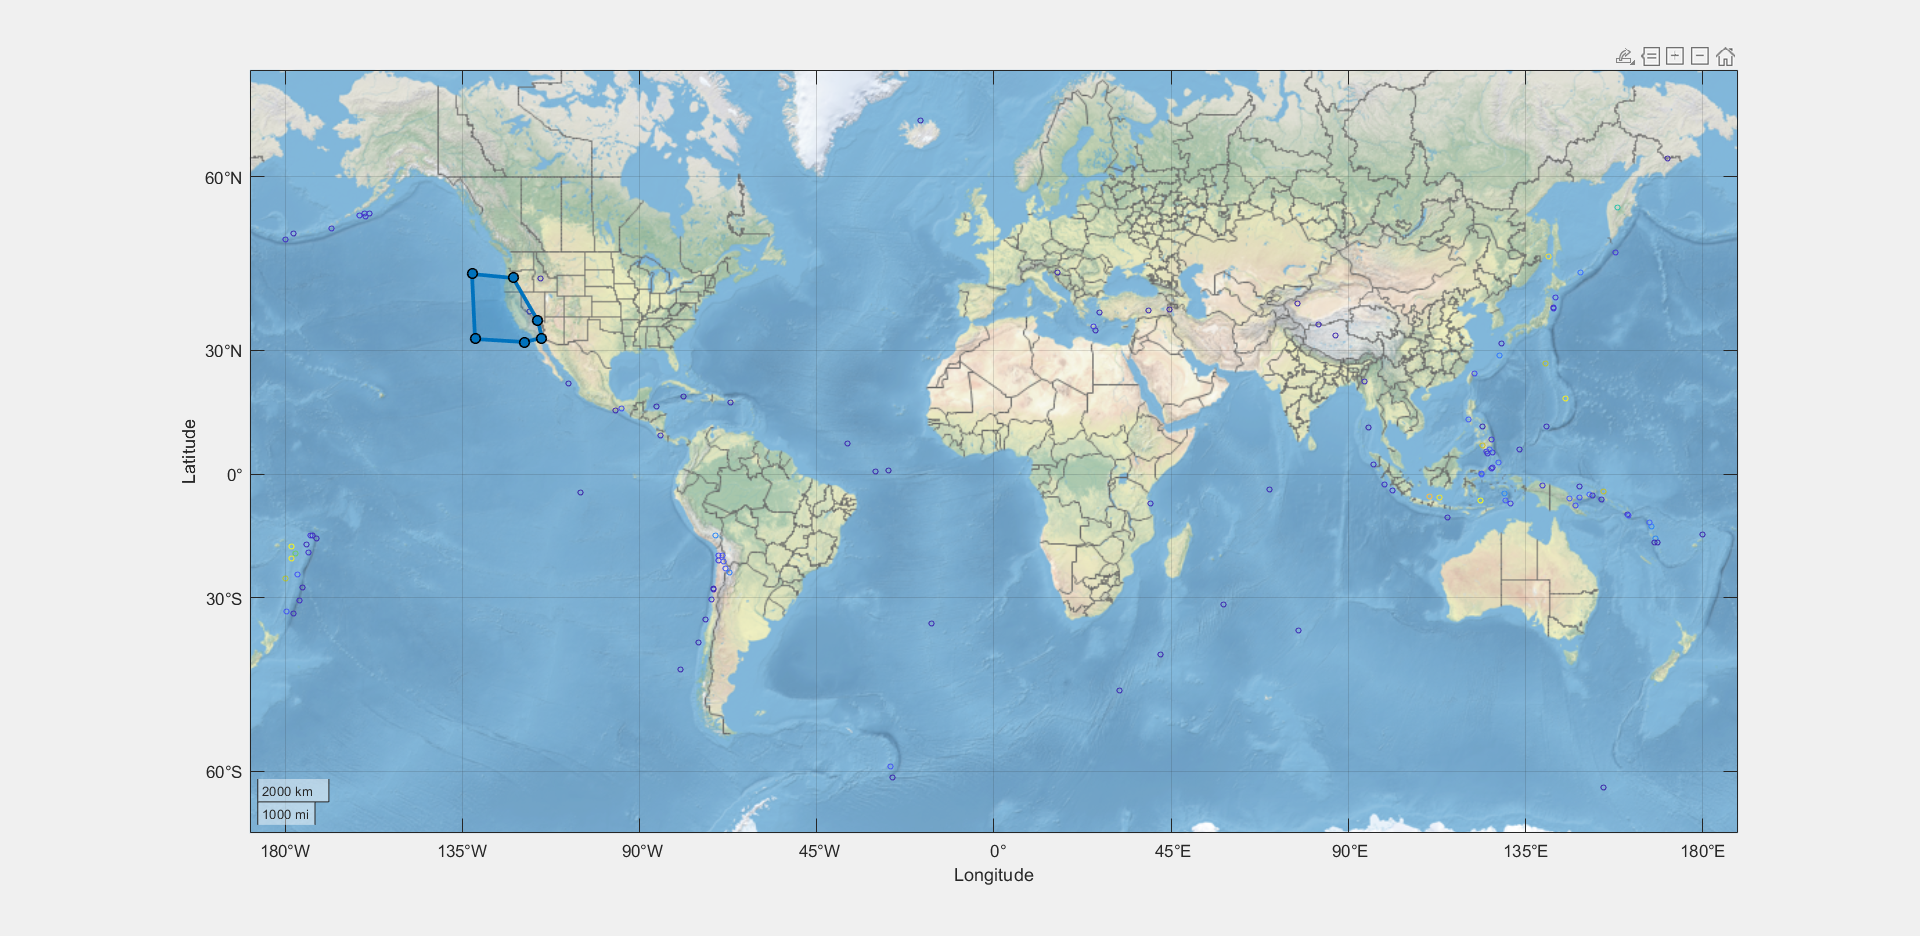

% Press button plot the polygon selection map

plot_map = 1;
if search_type == 'P' && plot_map == 1
    
    % Plot seismicity map
    disp('Plot map for polygon selection ...')

    % Select points on the map
    [poly_lats, poly_lons] = define_polygon_latlon();

    % Define a string of lats and lons needed for the ISC web request
    [poly_string] = define_polygon_string(poly_lats, poly_lons);
else
    poly_string = [];
end


plot_map = 1;

download_data = 0;

Click the button below to send data request to the ISC website:

 

if exist('download_data') == false
    disp ('!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!');
    disp (' Error: Must run the live script before downloading data.');
    disp ('        Click green "Run" button in the LIVE EDITOR ribbon (above)');
    disp ('!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!');
end

if download_data == 1

    % Start the download
    disp('Start Data Download ...');
    
    % Make all input string 9 characters long
    x = search_type;

    while numel(x) < 9
        x = sprintf('%s ', x);
        request = x;
    end

    % Define the request string from various inputs commands
    strtrim(request);
    if (x == 'G        ') | (x == 'g        ') | (x == 'GLOB     ') | (x == 'GLOBAL   ') | (x == 'glob     ') | (x == 'global   ')
        request = 'GLOBAL   '; clear x prompt;
        poly_string = 0.0;
    elseif (x == 'C        ') | (x == 'c        ') | (x == 'CIRC     ') | (x == 'CIRCLE   ') | (x == 'circ     ') | (x == 'circle   ')
        request = 'CIRCLE   ';  clear x prompt;
    elseif (x == 'R        ') | (x == 'r        ') | (x == 'RECT     ') | (x == 'RECTANGLE') | (x == 'rect     ') | (x == 'rectangle')
        request = 'RECTANGLE'; clear x prompt;
    elseif (x == 'P        ') | (x == 'p        ') | (x == 'POLY     ') | (x == 'POLYGON  ') | (x == 'poly     ') | (x == 'polygon  ')
        request = 'POLYGON  '; clear x prompt;
    end
    request = strtrim(request);

    % Define and make web request
    start_datetime = datetime(start_year, start_month, start_day, start_hour, start_minute, start_second);
    end_datetime = datetime(end_year, end_month, end_day, end_hour, end_minute, end_second);

    depth_limits = [min_depth, max_depth];
    magnitude_limits = [min_mag, max_mag];
    phases_limits = [-inf, inf];

    %[allPrimes, allHypocentres, allMagnitudes, allPhases] = download_ISC_data0_2( ...
    %    start_datetime, end_datetime, ...
    %    depth_limits, magnitude_limits, phases_limits, ...
    %    magnitude_type, magnitude_author, ...
    %    IncludePhases = "off", IncludeMagnitudes = "on", ...
    %    IncludeLinks = "off", IncludeHeaders = "on", ...
    %    IncludeComments = "on", Request = request, ...
    %    PolyString = poly_string);

    [allPrimes, allHypocentres, allMagnitudes, allPhases, allFocalMechanisms] = download_ISC_data0_2( ...
        start_datetime, end_datetime, ...
        depth_limits, magnitude_limits, phases_limits, ...
        magnitude_type, magnitude_author, ...
        IncludePhases = include_phases, IncludeMagnitudes = include_magnitudes, ...
        IncludeLinks = "off", IncludeHeaders = include_headers, ...
        IncludeComments = include_comments, Request = request, ...
        PolyString = poly_string);

    disp('... Data Download Complete');
end

Start Data Download ...



download_data = 1;

% if exist('allPrimes') == false
%     disp ('!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!');
%     disp (' Error: No data found - try a broader search');
%     disp ('        Specifically, try extending the search to lower magnitudes, or');
%     disp ('        increasing the time period, or looking at a larger area.');
%     disp ('!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!');
% end

Once data download is complete, define the filename and save the data as a MATLAB '.mat' file below. This will enable you to use this data freely in other MATLAB scripts or programmes.

NOTE: The datanloaded_ISC_Data/Japan_2018_2021_mb4_0plus download must have completed before you save thenloaded_ISC_Data/Afganistan_1964_2023_ISCmb3_0plus data. Otherwise it will cause an error.

save_data = 0;

save_file_default = 'Data/Dowloaded_ISC_Data/my_data.mat';
save_file = "Data/Downloaded_ISC_Data/mendocino";
save_file = sprintf('%s.mat', save_file);

disp('Data will be saved to:')
disp(save_file)

Data/Downloaded_ISC_Data/mendocino.mat



 

if save_data == 1

    if numel(save_file) == 4
        disp('ERROR: Please define filename to save to')
    else

        if (output_phases == 1)
            save(save_file, 'allPrimes', 'allHypocentres', 'allMagnitudes', 'allFocalMechanisms', 'allPhases')
        else
            save(save_file, 'allPrimes', 'allHypocentres', 'allMagnitudes', 'allFocalMechanisms')
        end

    end

    clear default_* start_* end_* include_* magnitude_* min_* max_* output_* save_* download_data plot_map poly_string request search_type;
    % clear all*;
end

save_data = 1;
if save_data == 2
    clear save_data;
end